% Supplementary Analysis 3b - Translating adult lesion-symptom models to predict late childhood stroke outcomes

clc;
clear all;

% Add statistical scripts to path
addpath('/Shared/boeslab/Users/jcgriffis/statistical_scripts/Misc_Code');
addpath('/Shared/boeslab/Users/jcgriffis/vips_psom_prediction/final_archive_scripts');

% Analysis parameters
min_stroke_age = 5; % Minimum stroke onset age (years)
max_stroke_age = 19; % Maximum stroke onset age (years)
min_test_age = 0; % Minimum age at PSOM (years)
min_test_interval = 0.5; % Minimum interval between onset and assessment (years)
min_freq = 1; % Minimum lesion frequency
pos_only = 1; % Use only positive model weights for predictions
get_vips_preds = 0; % load test fold predictions for pediatric models when generating adult model predictions

% Path to adult SM model
sm_col = "gpb_dif";
sm_outcome = "contra_motor";    
sm_dir = '/Shared/boeslab/Users/jcgriffis/vips_psom_prediction/registry_models/motor';    
sm_model_dir = 'plsr_all_lesion_d0_all_flip_ui';
sm_model_path = fullfile(sm_dir, sm_col, sm_model_dir); 

% Path to adult Lang model
lang_col = "mae_token";
lang_outcome = "worst_lang";    
lang_dir = '/Shared/boeslab/Users/jcgriffis/vips_psom_prediction/registry_models/language';   
lang_model_dir = 'plsr_all_lesion_d0_all_ui';    
lang_model_path = fullfile(lang_dir, lang_col, lang_model_dir); 

% Get predicted pediatric scores (SM)
[cfg_sm, beh_csv] = load_and_format_vips_lesions(sm_outcome);

All subjects with behavioral data have lesion files, N=528 patients will be included


if pos_only == 1
    [~, ui_pred_sm, vips_pred_sm] = apply_ui_model_vips(sm_col, sm_model_path, cfg_sm, beh_csv, get_vips_preds,...
        sm_outcome, min_stroke_age, min_test_age, min_test_interval, min_freq, 0, pos_only);
else
    [ui_pred_sm, ~, vips_pred_sm] = apply_ui_model_vips(sm_col, sm_model_path, cfg_sm, beh_csv, get_vips_preds,...
        sm_outcome, min_stroke_age, min_test_age, min_test_interval, min_freq, 0, pos_only);
end

    "Applying model for "    "gpb_dif"




% Get predicted pediatric scores (lang)
[cfg_lang, beh_csv] =  load_and_format_vips_lesions(lang_outcome);

All subjects with behavioral data have lesion files, N=528 patients will be included


if pos_only == 1
    [~, ui_pred_lang, vips_pred_lang] = apply_ui_model_vips(lang_col, lang_model_path, cfg_lang, beh_csv, get_vips_preds,...
        lang_outcome, min_stroke_age, min_test_age, min_test_interval, min_freq, 0, pos_only);
else
    [ui_pred_lang, ~, vips_pred_lang] = apply_ui_model_vips(lang_col, lang_model_path, cfg_lang, beh_csv, get_vips_preds,...
        lang_outcome, min_stroke_age, min_test_age, min_test_interval, min_freq, 0, pos_only);
end

    "Applying model for "    "mae_token"



% Get indices of patients that meet inclusion criteria
inc_ind = find(all([beh_csv.stroke_age > min_stroke_age, beh_csv.stroke_age <= max_stroke_age, beh_csv.test_age >= min_test_age, beh_csv.yrs2test >= min_test_interval],2));

% Subset dataset and predictions to retain only included patients
beh_csv = beh_csv(inc_ind,:);
ui_pred_sm = ui_pred_sm(inc_ind);
ui_pred_lang = ui_pred_lang(inc_ind);
disp(['N=' num2str(length(inc_ind)) ' included pediatric patients'])

N=315 included pediatric patients


% Define standardized covariates
covs = zscore([beh_csv.lh_vol, beh_csv.rh_vol, beh_csv.stroke_age, beh_csv.yrs2test]);

% Can adult model predictions be used to classify pediatric impairment status?

% ROC AUC analysis (SM)
roc_pred_sm = rocmetrics(beh_csv.(sm_outcome) > 0.5, ui_pred_sm, 1, 'NumBootstraps', 1000); 
perm_Y = beh_csv.(sm_outcome) > 0.5;
perm_auc = zeros(1000,1);
for i = 1:1000 % Permutation test
    perm_Yi = perm_Y(randperm(length(perm_Y)));
    roc_perm = rocmetrics(perm_Yi > 0.5, ui_pred_sm, 1);
    perm_auc(i,1) = roc_perm.auc;
end
perm_p_sm = (numel(find(perm_auc > roc_pred_sm.auc))+1)./1001    

perm_p_sm = 9.9900e-04

[a1, l1, u1] = auc(roc_pred_sm)

a1 = single
0.7651

l1 = single
0.6949

u1 = single
0.8283

% ROC AUC analysis (Lang)
roc_pred_lang = rocmetrics(beh_csv.(lang_outcome) > 0.5, ui_pred_lang, 1, 'NumBootstraps', 1000); 
perm_Y = beh_csv.(lang_outcome) > 0.5;
perm_auc = zeros(1000,1);
for i = 1:1000 % Permutation test
    perm_Yi = perm_Y(randperm(length(perm_Y)));
    roc_perm = rocmetrics(perm_Yi > 0.5, ui_pred_lang, 1);
    perm_auc(i,1) = roc_perm.auc;
end
perm_p_lang = (numel(find(perm_auc > roc_pred_lang.auc))+1)./1001

perm_p_lang = 9.9900e-04

[a2, l2, u2] = auc(roc_pred_lang)

a2 = single
0.7908

l2 = single
0.6898

u2 = single
0.8715

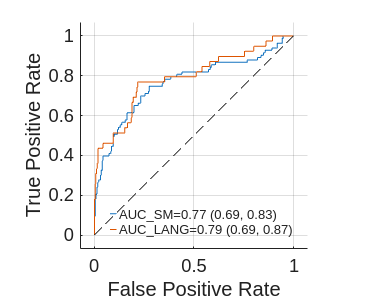


% Plot ROC curves
clf;
plot(roc_pred_sm, 'ShowModelOperatingPoint', false);
hold on;
plot(roc_pred_lang, 'ShowModelOperatingPoint', false);
lgd = legend({['AUC_SM=' num2str(round(a1,2)) ' (' num2str(round(l1,2)) ', ' num2str(round(u1,2)) ')']...
    ['AUC_LANG=' num2str(round(a2,2)) ' (' num2str(round(l2,2)) ', ' num2str(round(u2,2)) ')']}, 'FontSize', 10);
lgd.IconColumnWidth = 5;
legend('box', 'off')
grid on; set(gcf, 'position', [0, 0, 375, 300]); set(gca, 'FontSize', 14); title('');

% Do predicted scores correlate with observed pediatric scores?

% Get correlations
[r_pred_sm, p_pred_sm] = corr(ui_pred_sm, beh_csv.(sm_outcome), 'type', 'Spearman', 'rows', 'pairwise')

r_pred_sm = single
0.4393

p_pred_sm = single
2.7140e-16

[r_pred_lang, p_pred_lang] = corr(ui_pred_lang, beh_csv.(lang_outcome), 'type', 'Spearman', 'rows', 'pairwise')

r_pred_lang = single
0.4178

p_pred_lang = single
9.6786e-15

% Get CIs
bootfun = @(IV,DV) corr(IV, DV, "Type", "spearman", "rows", "pairwise");
ci_pred_sm = bootci(1000,{bootfun,ui_pred_sm, beh_csv.(sm_outcome)}, "type", "normal")

ci_pred_sm = 2×1 single column vector
    0.3405
    0.5381


ci_pred_lang = bootci(1000,{bootfun,ui_pred_lang, beh_csv.(lang_outcome)}, "type", "normal")

ci_pred_lang = 2×1 single column vector
    0.3179
    0.5191


% get partial correlations
[pr_pred_sm, pp_pred_sm] = partialcorr(ui_pred_sm, beh_csv.(sm_outcome), covs, 'type', 'Spearman', 'rows', 'pairwise')

pr_pred_sm = single
0.3014

pp_pred_sm = single
5.9633e-08

[pr_pred_lang, pp_pred_lang] = partialcorr(ui_pred_lang, beh_csv.(lang_outcome), covs, 'type', 'Spearman', 'rows', 'pairwise')

pr_pred_lang = single
0.2263

pp_pred_lang = single
5.6656e-05

% Get CIs
bootfun = @(IV,DV, covariates) partialcorr(IV, DV, covariates, "Type", "spearman", "rows", "pairwise");
ci_pred_pr_sm = bootci(1000, {bootfun, ui_pred_sm, beh_csv.(sm_outcome), covs}, "type", "normal")

ci_pred_pr_sm = 2×1 single column vector
    0.1864
    0.4102


ci_pred_pr_lang = bootci(1000, {bootfun, ui_pred_lang, beh_csv.(lang_outcome), covs}, "type", "normal")

ci_pred_pr_lang = 2×1 single column vector
    0.1219
    0.3229


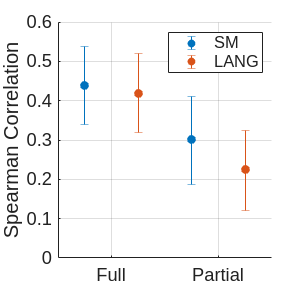

% Plot correlation results
clf;
errorbar(0.75, r_pred_sm, r_pred_sm-ci_pred_sm(1), ci_pred_sm(2)-r_pred_sm, 'LineStyle', 'none', 'Marker', '.', 'MarkerSize', 20,'Color', [0, 0.447, 0.741]);
hold on;
errorbar(1.25, r_pred_lang, r_pred_lang-ci_pred_lang(1), ci_pred_lang(2)-r_pred_lang, 'LineStyle', 'none', 'Marker', '.', 'MarkerSize', 20,'Color', [0.85, 0.325, 0.098]);
errorbar(1.75, pr_pred_sm, pr_pred_sm-ci_pred_pr_sm(1), ci_pred_pr_sm(2)-pr_pred_sm, 'LineStyle', 'none', 'Marker', '.', 'MarkerSize', 20,'Color', [0, 0.447, 0.741]);
errorbar(2.25, pr_pred_lang, pr_pred_lang-ci_pred_pr_lang(1), ci_pred_pr_lang(2)-pr_pred_lang, 'LineStyle', 'none', 'Marker', '.', 'MarkerSize', 20,'Color', [0.85, 0.325, 0.098]);
ylim([0, 0.6]);
xlim([0.5, 2.5])
set(gca, 'Xtick', [1:1:2]);
set(gca, 'XtickLabel', {'Full', 'Partial'});
ylabel('Spearman Correlation');
legend({'SM', 'LANG'}); box off;
grid on; set(gcf, 'position', [0, 0, 300, 290]); set(gca, 'FontSize', 14); title(''); 

% Fit ordinal logistic regression models to estimate aOR and compare against base models

% Reverse code and re-code categories to set reference category to unimpaired (SM outcome)
Y1 = zeros(length(inc_ind),1);
Y1(beh_csv.(sm_outcome)==0)=3;
Y1(beh_csv.(sm_outcome)==0.5)=2;
Y1(beh_csv.(sm_outcome)==1)=1;
Y1(beh_csv.(sm_outcome)==2)=0;
Y1 = categorical(Y1);

% Reverse code and re-code categories to set reference category to unimpaired (LANG outcome)
Y2 = zeros(length(inc_ind),1);
Y2(beh_csv.(lang_outcome)==0)=3;
Y2(beh_csv.(lang_outcome)==0.5)=2;
Y2(beh_csv.(lang_outcome)==1)=1;
Y2(beh_csv.(lang_outcome)==2)=0;
Y2 = categorical(Y2); 

% Fit base OLR models
mdl1a = fitmnr(covs, Y1, 'ModelType', 'ordinal', 'PredictorNames', {'LH Volume', 'RH Volume', 'Age at Stroke', 'Time to Test'}); % SM Model
mdl2a = fitmnr(covs, Y2, 'ModelType', 'ordinal', 'PredictorNames', {'LH Volume', 'RH Volume', 'Age at Stroke', 'Time to Test'}); % LANG Model   

% Add adult predictions (SM)
mdl1b = fitmnr([covs, zscore(ui_pred_sm)], Y1, 'ModelType', 'ordinal', 'IterationLimit', 1000, 'PredictorNames', {'LH Volume', 'RH Volume', 'Age at Stroke', 'Time to Test', 'Adult Model'})

mdl1b = Multinomial regression with ordinal responses

                       Value        SE        tStat        pValue  
                     _________    _______    ________    __________

    (Intercept_0)      -2.8504    0.24126     -11.815    3.2787e-32
    (Intercept_1)      -1.1924    0.14436     -8.2598    1.4588e-16
    (Intercept_2)     0.034707    0.12185     0.28483       0.77577
    LH Volume          0.10322    0.20043     0.51499       0.60656
    RH Volume        -0.033842    0.19566    -0.17296       0.86268
    Age at Stroke    -0.076132    0.11513    -0.66124       0.50846
    Time to Test      0.097925     0.1125     0.87046       0.38405
    Adult Model         1.0212    0.24138      4.2307    2.3

% Add adult predictions (Lang)
mdl2b = fitmnr([covs, zscore(ui_pred_lang)], Y2, 'ModelType', 'ordinal', 'IterationLimit', 1000, 'PredictorNames', {'LH Volume', 'RH Volume', 'Age at Stroke', 'Time to Test', 'Adult Model'})

mdl2b = Multinomial regression with ordinal responses

                      Value        SE        tStat        pValue  
                     ________    _______    ________    __________

    (Intercept_0)     -4.1892    0.39089     -10.717    8.4523e-27
    (Intercept_1)      -2.411    0.21369     -11.283    1.5993e-29
    (Intercept_2)     -1.3232    0.15317     -8.6387     5.684e-18
    LH Volume        -0.22494    0.45011    -0.49975       0.61725
    RH Volume         0.21418    0.11921      1.7967      0.072382
    Age at Stroke    -0.11661    0.14767    -0.78963       0.42974
    Time to Test      0.40246    0.13194      3.0503      0.002286
    Adult Model        1.1655      0.446      2.6133     0.0089669




% Get coeffs and CIs
mdl1b_ci = coefCI(mdl1b); mdl1b_ci = exp(mdl1b_ci(4:end,:));
mdl2b_ci = coefCI(mdl2b); mdl2b_ci = exp(mdl2b_ci(4:end,:));
mdl1b_coef = exp(mdl1b.Coefficients.Value(4:end));
mdl2b_coef = exp(mdl2b.Coefficients.Value(4:end));

% Likelihood ratio tests of expanded vs. base models
p_llr_sm = 1-chi2cdf(-2*(mdl1a.LogLikelihood-mdl1b.LogLikelihood),1) % SM 

p_llr_sm = single
2.5153e-05

p_llr_lang = 1-chi2cdf(-2*(mdl2a.LogLikelihood-mdl2b.LogLikelihood),1) % Lang

p_llr_lang = single
0.0070

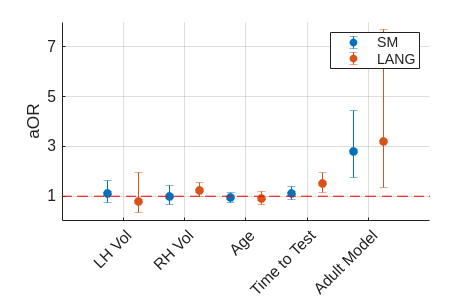

% Plot aORs and 95% CIs
clf;
errorbar([0.75,1.75,2.75,3.75,4.75], mdl1b_coef, mdl1b_coef-mdl1b_ci(:,1), mdl1b_ci(:,2)-mdl1b_coef, 'LineStyle', 'none', 'Marker', '.', 'MarkerSize', 20,'Color', [0, 0.447, 0.741]);
hold on;
errorbar([1.25,2.25,3.25,4.25, 5.25], mdl2b_coef, mdl2b_coef-mdl2b_ci(:,1), mdl2b_ci(:,2)-mdl2b_coef, 'LineStyle', 'none', 'Marker', '.', 'MarkerSize', 20,'Color', [0.85, 0.325, 0.098]);
line([0, 6], [1, 1], 'LineStyle', '--', 'Color', 'r', 'LineWidth', 0.5);
ylabel('aOR'); grid on; legend({'SM', 'LANG'});
set(gca, 'Xtick', 1:1:5);
set(gca, 'XtickLabel', {'LH Vol', 'RH Vol', 'Age', 'Time to Test', 'Adult Model'});
set(gca, 'XtickLabelRotation', 45);
set(gca, 'FontSize', 12);
set(gcf, 'color', 'w');
set(gca, 'Ytick', 1:2:9)
set(gcf, 'position', [0, 0, 475, 300]); box off;